# Matlab Introduction: Scripts

Make sure you've watched the "Introduction" video on Moodle before you go any further. The video makes a number of important points, summarised here:

- The Matlab Command Window (the focus of part 1) is great for trying out small things, but it's no good for more complicated tasks involving lots of lines of code

- We need somewhere where we can save all our code, comment it, run it all with a single click, and return to it to make changes

- Matlab solves this problem by letting us save multiple lines of code (plus comments) in a *script* (with the file extension .m)

- A new script can be created by clicking the "New Script" button, and an example script containing some of the lines of code we used in part 1 is provided on Moodle, which you should open and try running

- Before you can run a script, you need to save it in a sensible place (e.g., H: drive or a pen drive that you always carry with you - certainly somewhere that you keep backed up if the script is important) and then you need to navigate to that folder using the Matlab Current Folder pane

- To run the script you can either type its name, excluding the '.m' at the end, into the Matlab Command Window OR you can open it up (by double clicking it in the Current Folder pane) and click on the large green "Run" button

- All the output generated by the script will still appear on the Command Window and...

- All of the variables created by the script will still appear in the Workspace.

- As an alternative to normal scripts, Matlab also offers *live scripts* (with the extension .mlx)

- Live scripts are the same as normal scripts in all but two ways...

- First, they let us embed rich text and images (rather than just plain text comments)

- Second, the output they produce appears inside the script itself, instead of in the Command Window.

- Live scripts are specifically designed for educational scenarios, like ours, where we need more than just plain text comments, and where continually switching between the script and the Command Window can be awkward.

- Note that the variables are still created in the Workspace after running a live script.

- We will work in live scripts (extension .mlx) from now on.

Make sure you're happy about everything covered by the video before continuing, particularly the difference between Matlab *scripts* (with the extension .m) and Matlab *live scripts* (with the extension .mlx). If you're not sure about anything then ask your tutor.

## Normal scripts

The script part2_script.m contains some of the key commands we entered in part 1, brought together in a script. Make sure you can run the script, see the output it produces in the Command Window, and the variables it creates in the Workspace, before going any further. If you're struggling to get it to work, then make sure you've watched the "Introduction" video and read through the summary of important points above. Remember you need to have the Matlab Current Folder pointing at the folder on your computer where you saved the script. Remember that you can run a script by opening it up (double click it in the Current Folder pane) and clicking the green "Run" button at the top of the editor window OR by typing the name of the script excluding the '.m', into the Command Window.

## Live scripts

Now let's see a live script version of the same script. You're reading rich text in a live script right now, so let's add some code:

foo = 'bar'

foo = 'bar'

If you click the green "Run" button up at the top of the editor, then all the code in the live script will run, and:

- You'll see the output appearing *in the live script itself*

- Any variables created will appear in the Matlab Workspace as usual

Try clicking the green "Run" button now!

One of the useful features of a live script is that we can embed rich text and images. Here is a picture of the green "Run" button in case you're struggling to find it:

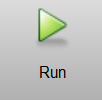

Below are the other commands we met in part 1. Check you recognise them and understand what each one is doing (ask for help if you're not sure):

num1 = 7

num1 = 7

num2 = 7.0002

num2 = 7.0002

num3 = num1 + num2

num3 = 14.0002

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


myarray(4) = 10

myarray =      3     7     5    10     1     5     9


myarray_min = min(myarray)

myarray_min = 1

myarray_max = max(myarray)

myarray_max = 10

myarray_average = mean(myarray)

myarray_average = 5.7143

myarray_total = sum(myarray)

myarray_total = 40

myarray_sorted = sort(myarray)

myarray_sorted =      1     3     5     5     7     9    10


myarray_unique = unique(myarray)

myarray_unique =      1     3     5     7     9    10


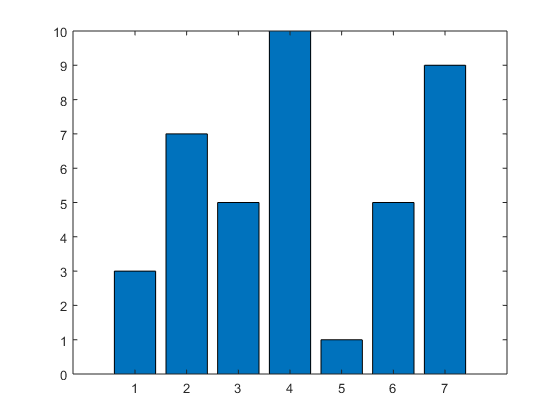

bar(myarray)

## Take a minute...

Take a final moment to check you're happy with scripts and live scripts, and the differences between them. From now on, the lab sheets you work through will typically be a live script, just like this one. But we'll also be making use of normal scripts as well, and you need to be comfortable with both. If you have any questions, then it's best to ask them now.

If you're happy then we're going to move on to learn more about Matlab and how it works...

## Creating arrays of evenly spaced numbers

This might not sound like the most useful topic, but bear with it... We're going to introduce some really powerful Matlab notation. Imagine I asked you to create an array containing evenly spaced numbers between a certain range. For example, all the numbers between 1 and 5. 

You could type the following at the Matlab Command Window and that would certainly work:

newarray = [1 2 3 4 5] 

newarray =      1     2     3     4     5


The problem is that this gets pretty awkward to do for large ranges. For example, if I asked for all the numbers between 1 and 100, you'd be there typing at the Command Window for a long time. And if I asked for the numbers not to be evenly spaced in jumps of 1, but in jumps of 3 then you'd have to do less typing but probably more thinking. (Please don't try it... We're going to see a better way.)

Hopefully, as a Computer Science student, you'd want to write a loop that builds the array for you. This would be a good solution in other languages, and it will work just fine in Matlab too (we'll come back to looping a little later...), but Matlab offers an even more convenient way.

Matlab allows you to use the following double-colon notation to generate an array of evenly spaced numbers between a certain range. The general format is:

<start_value>:<jump_size>:<end_value>

Have a look at the output from the following examples:

newarray = 1:1:10

newarray =      1     2     3     4     5     6     7     8     9    10


newarray = 1:3:25

newarray =      1     4     7    10    13    16    19    22    25


newarray = 11:4:30

newarray =     11    15    19    23    27


newarray = 10:-1:1

newarray =     10     9     8     7     6     5     4     3     2     1


newarray = -5:1:5

newarray =     -5    -4    -3    -2    -1     0     1     2     3     4     5


Each command generates an array of evenly spaced numbers which is stored inside the `newarray` variable. Check you're happy with how the double-colon notation works before you move on. You should be comfortable with why each of the examples above produces the output that it does. Double-colon notation is used a lot when coding in Matlab, so it's best to put your hand up and ask a question about it now if you're not sure what's going on. Use double-colon notation to complete the following tasks before moving on to the next section:

Task 1:

% use double-colon notation to output numbers between 10 to 20 in jumps of 1:
% type your solution on the line below:
newarray = 10:1:20

newarray =     10    11    12    13    14    15    16    17    18    19    20


Task 2:

% use double-colon notation to output numbers between 30 to 20 in jumps of -1:
% type your solution on the line below:
newarray = 30:-1:20

newarray =     30    29    28    27    26    25    24    23    22    21    20


Task 3:

% use double-colon notation to output numbers between -3 to 3 in jumps of 0.5:
% type your solution on the line below:
newarray = -3:0.5:3

newarray =    -3.0000   -2.5000   -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000


## More on array indexing

Now you know about the double-colon notation, let's have another look at indexing the elements of an array. First let's recreate the `myarray` variable to play around with:

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


We already know that we can index a single element of the array with normal brackets notation and a 1-based index:

% take a copy of the 4th element of our array:
mycopy = myarray(4)

mycopy = 2

But actually, we aren't limited to putting a single number inside the brackets to refer to a single element. We can put an array inside the brackets to refer to a set of elements. For example, the following command takes a copy of the odd-numbered elements of the array: 1, 3, 5 and 7:

% take a copy of the odd-numbered elements of our array:
mycopy = myarray([1 3 5 7])

mycopy =      3     5     1     9


Now, we can rewrite that command in a simpler form using our double-colon notation:

% take a copy of the odd-numbered elements of our array:
mycopy = myarray(1:2:7)

mycopy =      3     5     1     9


(Remember from the previous section that the `1:2:7` generates an evenly spaced array of numbers:)

1:2:7

ans =      1     3     5     7


Now, the best bit of all... When you use double-colon notation to refer to array elements in this way, Matlab will spot what you're doing and try to help. The most useful thing it does is to automatically find the size of the array you're referring to and store it in a variable called `end`. This means that instead of having to remember how big your array is, you can just write something like this:

% take a copy of the odd-numbered elements of our array:
mycopy = myarray(1:2:end)

mycopy =      3     5     1     9


The `end` variable doesn't exist in the Matlab Workspace like a normal variable. You can only access it when you are using double-colon notation to refer to an array and it will store different values depending on which array you're referring to. But you can always rely on it being correct, and it's very handy.

Let's see some more examples:

% take a copy of the even-numbered elements of our array:
mycopy = myarray(2:2:end)

mycopy =      7     2     5


% take a copy of the last element of our array:
mycopy = myarray(end)

mycopy = 9

% take a copy of the last 3 elements of our array:
mycopy = myarray(end-2:1:end)

mycopy =      1     5     9


So far, we've only taken copies of the values in our original array, but double-colon notation also allows you to edit the original array quickly and conveniently.

Here we set all the odd-numbered elements in our array to 17:

myarray(1:2:end) = 17

myarray =     17     7    17     2    17     5    17


Here we add two onto the current value of all the even-numbered elements:

myarray(2:2:end) = myarray(2:2:end) + 2

myarray =     17     9    17     4    17     7    17


Here we set all the values to zero:

myarray(1:1:end) = 0

myarray =      0     0     0     0     0     0     0


Here we set the first three elements to 5:

myarray(1:1:3) = 5

myarray =      5     5     5     0     0     0     0


And remember, if there's no pattern to the array elements you need to write, and it's not possible to reference them using double-colon notation, then you can always index them manually, by typing your own array. For example, here we set the 1st, 2nd, 4th and last elements of the array to -1 (note you still have access to the `end` variable when you're typing your array):

myarray([1 2 4 end]) = -1

myarray =     -1    -1     5    -1     0     0    -1


Take some time to read the examples carefully and check you're happy with what's going on. Then try the tasks below.

Here's a much larger array to play with. Use double-colon notation, and the `end` variable where appropriate, to complete the following tasks:

bigarray = 1:1:100

bigarray =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Task 1:

% take a copy of the odd-numbered elements of bigarray, and store them in a variable called mycopy:
% type your solution on the line below:
mycopy = bigarray(1:2:end)

mycopy =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51    53    55    57    59    61    63    65    67    69    71    73    75    77    79    81    83    85    87    89    91    93    95    97    99


Task 2:

% take a copy of the last 30 elements of bigarray, and store them in a variable called mycopy:
% type your solution on the line below:
mycopy = bigarray(end-29:1:end)

mycopy =     71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100


Task 3:

% take a copy of the first 30 elements of bigarray, and store them in a variable called mycopy:
% type your solution on the line below:
mycopy = bigarray(1:1:30)

mycopy =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


Task 4:

% set the first 10 elements of bigarray to hold the value -11:
% type your solution on the line below:
bigarray(1:1:10) = -11

bigarray =    -11   -11   -11   -11   -11   -11   -11   -11   -11   -11    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


Task 5:

% add 7 to the last 15 elements of bigarray:
% type your solution on the line below:
bigarray(end-14:1:end) = bigarray(end-14:1:end)+7

bigarray =    -11   -11   -11   -11   -11   -11   -11   -11   -11   -11    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


## Using other operators on arrays

We saw above how easy it is to add a value to every element of an array. Subtracting is similarly easy, and multiplying or dividing all elements by single numbers is also easy:

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


myarray + 2

ans =      5     9     7     4     3     7    11


myarray - 2

ans =      1     5     3     0    -1     3     7


myarray * 2

ans =      6    14    10     4     2    10    18


myarray / 2

ans =     1.5000    3.5000    2.5000    1.0000    0.5000    2.5000    4.5000


Things get a little bit more complicated when you want to do these things with *another array* and have the operation take place on an element-by-element basis. Things still work fine for addition and subtraction:

% add myarray to myarray:
myarray + myarray

ans =      6    14    10     4     2    10    18


% subtract myarray from myarray:
myarray - myarray

ans =      0     0     0     0     0     0     0


But if you were to try multiplying or dividing `myarray` by itself you would get an error (try it in the Command Window if you're interested). This is because Matlab assumes you are asking to do a mathematical operation called vector multiplication (or division) which works a bit differently (requires you to turn one of the arrays on its end). Vector operations are beyond the scope of this unit and we don't need to worry about them, we just need to define how to do the "normal" element-by-element versions of those operations, and this is easy - you just add a preceding dot:

% add a dot for element-by-element multiplication:
myarray .* myarray

ans =      9    49    25     4     1    25    81


% add a dot for element-by-element division:
myarray ./ myarray

ans =      1     1     1     1     1     1     1


The same is true if you want to do an element-by-element power with Matlab. That is, if you want to multiply every element in an array by itself a number of times. Here are a couple of examples showing every element of myarray to its second power, and then to its fourth power:

% add a dot for element-by-element powers:
myarray .^ 2

ans =      9    49    25     4     1    25    81


myarray .^ 4

ans =           81        2401         625          16           1         625        6561


Task 1:

% create an array called a1 holding the values 2 4 8 1 4 4 -2 and 3
% type your solution on the line below:
a1 = [2 4 8 1 4 4 -2 3]

a1 =      2     4     8     1     4     4    -2     3


Task 2:

% create an array called a2 holding the values 1 2 3 1 2 3 1 and 2
% type your solution on the line below:
a2 = [1 2 3 1 2 3 1 2]

a2 =      1     2     3     1     2     3     1     2


Task 3:

% subtract each of the values in a2 from each of the values in a1,
% storing the result in a new array called a3
% type your solution on the line below:
a3 = a1 - a2

a3 =      1     2     5     0     2     1    -3     1


Task 4:

% multiply each of the values in a3 by each of the values in a2,
% storing the result in a new array called a4
% type your solution on the line below:
a4 = a3 .* a2

a4 =      1     4    15     0     4     3    -3     2


Task 5:

% square each of the values in a1 and use the result to overwrite the original a1
% type your solution on the line below:
a1 = a1 .* a1

a1 =      4    16    64     1    16    16     4     9


## Everything is an array

Now for some big news about Matlab: Matlab actually treats all your variables as arrays.

Even back in our early examples, when we were assigning a single number to a variable name:

num1 = 7

num1 = 7

From Matlab's point of view, this was exactly equivalent to us using square bracket notation to define an array with only a single entry:

num1 = [7] % both this line and the last one do exactly the same thing, and you can swap them over if you like

num1 = 7

Matlab is also very flexible about what you do with arrays...

For example, you can add an extra element onto the end of an array any time you like, by using the `end` variable:

num1(end+1) = 8

num1 =      7     8


In fact, Matlab will even let you suddenly write a much higher element in your array, and will try to help out by storing sensible values (zeros) inside elements in between:

num1(10) = -2

num1 =      7     8     0     0     0     0     0     0     0    -2


You can also delete elements of an array by setting them equal to an empty array. The following command deletes the 3rd, 4th, 5th and 6th elements of the array:

num1(3:1:6) = []

num1 =      7     8     0     0     0    -2


So under the hood, Matlab is set up to store everything you give it as an array. And it offers a huge amount of flexibility over what you can do with those arrays, allowing you to update and reshape them over time with ease.

In most other languages, we have to think quite carefully about the size of our arrays, and work quite hard to make changes to them. But not in Matlab. We can be quite relaxed. For example, we will quite often create an empty array to store some values without thinking about how large it need to be in advance, and then, every time we need to add a value into it, just use the `end+1` notation:

stuff = []


stuff =

     []



% some time later...
stuff(end+1) = 5

stuff = 5

% some time later again...
stuff(end+1) = 54

stuff =      5    54


% perhaps many more times...
% stuff(end+1) = ...

## Shortcuts in double-colon notation

Let's return to double-colon notation for a while. There are two "shortcuts" it's useful to know about when you are writing double-colon notation.

The first is that if you omit the <jump_size> and only specify the <start_value> and <end_value>, then Matlab will assume a <jump_size> of 1. The general format is:

<start_value>:<end_value>

Have a look at the output from the following examples:

newarray = 1:10

newarray =      1     2     3     4     5     6     7     8     9    10


newarray = 5:17

newarray =      5     6     7     8     9    10    11    12    13    14    15    16    17


newarray = -5:5

newarray =     -5    -4    -3    -2    -1     0     1     2     3     4     5


The second shortcut is useful when using double-colon notation to index elements within an array (meaning the `end` variable is available). Specifically, it's useful when you want to specify *all *the elements of an array. The usual way to do this would be to write something like:

`myarray(1:1:end)`

Or based on the first shortcut we just learned about:

`myarray(1:end)`

But actually, in this specific case, Matlab will accept a single colon and nothing else as a shorthand for either of the statements above. Have a look at the following examples, which all do exactly the same thing, but using slightly different versions of the notation:

% the following three examples all do the same thing:

% double-colon notation:
myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


myarray(1:1:end) = 0

myarray =      0     0     0     0     0     0     0



% omitting the jump size causes Matlab to use a jump size of 1:
myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


myarray(1:end) = 0

myarray =      0     0     0     0     0     0     0



% a colon all by itself means "everything" (from 1 to end in jumps of 1)
myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


myarray(:) = 0

myarray =      0     0     0     0     0     0     0


It's generally up to you whether you want to use these shortcuts or not, but there are a handful of situations where Matlab needs you to specify all of an array and will *expect *you to use the second shortcut. The reasoning is basically that you can't get referring to all of an array wrong if you use a single colon, but you could feasibly mess it up if you used double-colon notation, so Matlab won't let you! We'll see an example of this in due course.

I quite like using double-colon notation in full because it makes it nice and clear to anyone reading my code what's happening. But there are also times when I forget and use a shortcut without thinking, and, as above, there are times when I have to use the second shortcut because Matlab insists on it.

Generally, it's up to you whether you want to use shortcuts in your own code, but you should be comfortable reading code and using code whether it uses shortcuts or not.

Task 1:

% Using an appropriate shortcut, create an array called s1 holding 
% the numbers from 10 to 20
% type your solution on the line below:
s1 = 10:20

s1 =     10    11    12    13    14    15    16    17    18    19    20


Task 2:

% Using an appropriate shortcut, set every value in s1 to 0
% type your solution on the line below:
s1(:) = 0

s1 =      0     0     0     0     0     0     0     0     0     0     0


## Logical indexing

We've done some interesting things around selectively indexing elements arrays, but all those things have been dependent on where the element falls within the array, rather than the value it contains. So for example, we've indexed all the odd-numbered elements, or all the elements with an index higher than 30, or just the first 10 elements.

Sometimes it's useful to make changes to elements of an array based on the values stored inside those elements. For example, to index all the elements holding the value zero, or to index all the elements holding a value of 10 or greater.

You can use logical indexing to perform this kind of task. Logical indexing uses an array of logical (true/false or 1/0) values to index an array. The logical array must contain a value for every element of the array: true if you do want to refer to it, or false if you don't. (Remember: we would normally refer to the elements we are interested in by supplying an array containing their 1-based indices.) Let's make a logical array and use it to refer to `myarray` as an example:

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


% make a logical array that will refer only to the odd-numbered elements of myarray:
logicalarr = [true false true false true false true]

logicalarr = 1×7 logical array
   1   0   1   0   1   0   1


% use it to index myarray:
myarray(logicalarr)

ans =      3     5     1     9


Now another really useful Matlab feature: you can ask Matlab to evaluate a logical condition on an array and it will loop over the array for you, testing whether the condition is true or false for the value contained inside every element of the array, and return to you a logical array holding the answers (true if the value met the condition, false if it did not):

logicalarr = myarray>4

logicalarr = 1×7 logical array
   0   1   1   0   0   1   1


And you can use the resulting array (`logicalarr`) to index your original array (`myarray`) with logical indexing:

myarray(logicalarr) % will return only the elements of the array containing a value greater than 4

ans =      7     5     5     9


If we put these steps together into a single command, it gives us quite a nice, natural way of referring to particular elements of an array, *based on the value they contain*:

myarray(myarray>4)

ans =      7     5     5     9


And just as we've done previously, we can use logical indexing to make changes the values inside our array. 

For example, changing them:

myarray(myarray<=3) = 0

myarray =      0     7     5     0     0     5     9


Updating them:

myarray(myarray>5) = myarray(myarray>5) + 2

myarray =      0     9     5     0     0     5    11


Or deleting them:

myarray(myarray==9) = []

myarray =      0     5     0     0     5    11


The final useful thing to know is that you can combine logical conditions with the `|` symbol for "OR" and the `&` symbol for "AND", and you can use the ~ symbol for "NOT".

For example:

myarray(myarray==0|myarray>10) = -7

myarray =     -7     5    -7    -7     5    -7


Check you're happy with how the logical indexing in this statement is working, and make sure you can complete the following tasks. Ask for help if you're not sure about anything:

Task 1:

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


% set all elements of myarray holding values less than or equal to 3 to the new value 10:
% type your solution on the line below:
myarray(myarray<=3) = 10

myarray =     10     7     5    10    10     5     9


Task 2:

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


% set all elements of myarray holding values less than or equal to 2 OR greater than 7 to the new value -3:
% type your solution on the line below:
myarray(myarray<=2|myarray>7) = -3

myarray =      3     7     5    -3    -3     5    -3


Task 3:

myarray = [3 7 5 2 1 5 9]

myarray =      3     7     5     2     1     5     9


% delete all elements of myarray holding the value 5:
% type your solution on the line below:
myarray(myarray==5) = []

myarray =      3     7     2     1     9
